%音声ファイルのリストの取得


%[audioIn,fs] = audioread('test_dataset/***.wav');



%dataSetDir = "C:\Users\Anzai Riki\Desktop\Creative_factory_bit_2022";
%signalDir = fullfile(dataSetDir,'test_dataset');
%sgds = signalDatastore(audioIn);


listing = dir('test_dataset/*.wav')

listing = フィールドをもつ 12×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


listing(1).name

ans = '2530_AV.wav'

length(listing)

ans = 12


%{
for n = 1:length(listing)
    % ファイルのフルパスを取得
    fullpath = fullfile(listing(n).folder, listing(n).name);
end
%}
%fullpath = fullfile('C:\Users\Anzai Riki\Desktop\Creative_factory_bit_2022\test_dataset\*.wav');

Number of bandpass filters in filterbank: 32


Number of frames in spectrogram: 2358


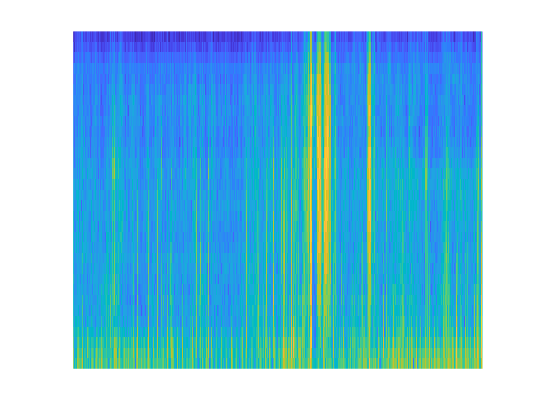

Number of bandpass filters in filterbank: 32


Number of frames in spectrogram: 2666


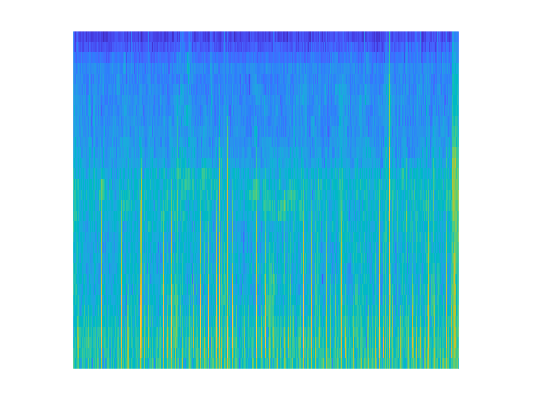

Number of bandpass filters in filterbank: 32


Number of frames in spectrogram: 1303


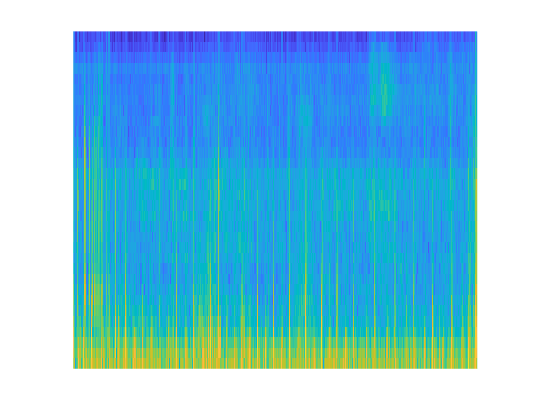

Number of bandpass filters in filterbank: 32


Number of frames in spectrogram: 1497


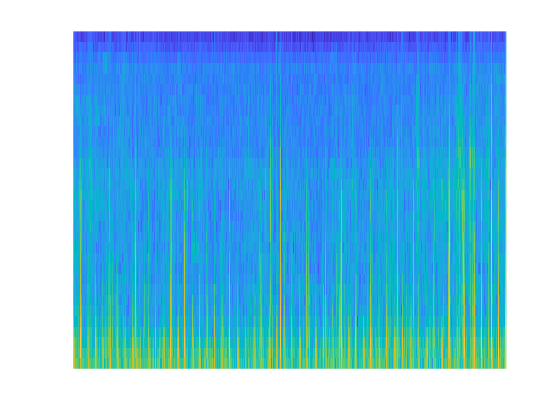

Number of bandpass filters in filterbank: 32


Number of frames in spectrogram: 2073


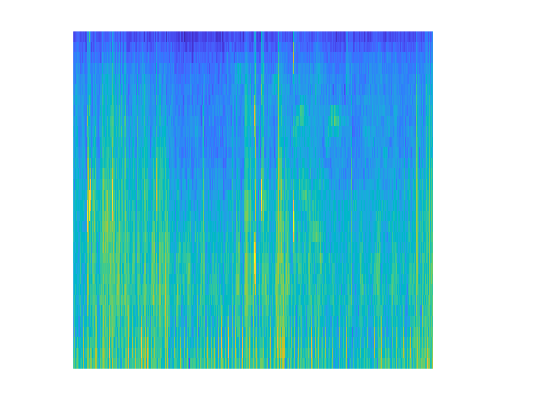

Number of bandpass filters in filterbank: 32


Number of frames in spectrogram: 2049


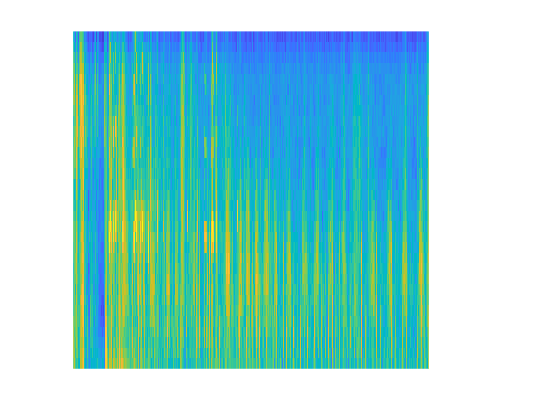

Number of bandpass filters in filterbank: 32


Number of frames in spectrogram: 1876


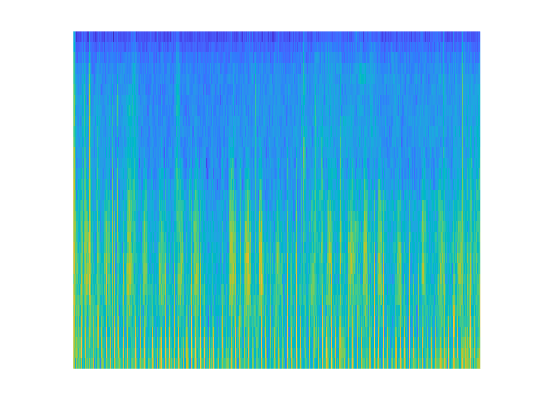

Number of bandpass filters in filterbank: 32


Number of frames in spectrogram: 2186


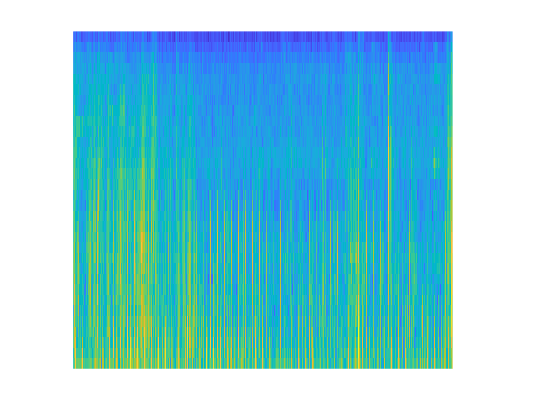

Number of bandpass filters in filterbank: 32


Number of frames in spectrogram: 1814


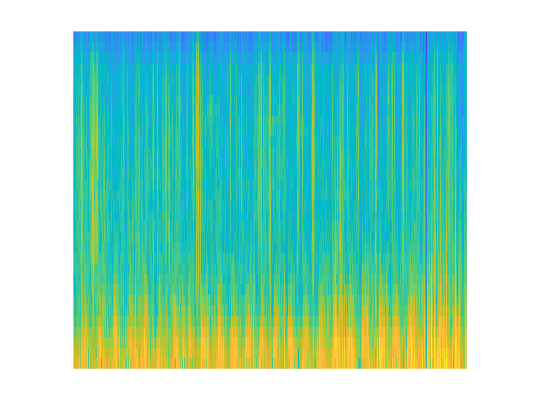

Number of bandpass filters in filterbank: 32


Number of frames in spectrogram: 2113


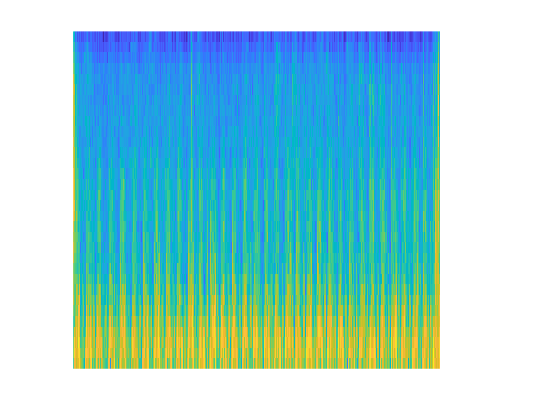

Number of bandpass filters in filterbank: 32


Number of frames in spectrogram: 2023


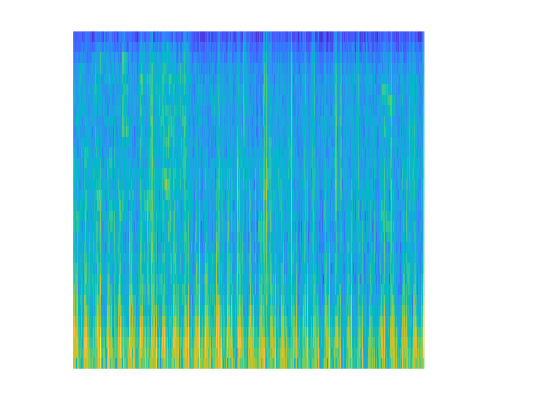

Number of bandpass filters in filterbank: 32


Number of frames in spectrogram: 2287


%メルスペクトログラム

for i = 1:length(listing)
    fullpath = fullfile(listing(i).folder, listing(i).name);
    [audioIn,fs] = audioread(fullpath);
    S = melSpectrogram(audioIn,fs);
    %plot(audioIn);
    [numBands,numFrames] = size(S);
    fprintf("Number of bandpass filters in filterbank: %d\n",numBands);
    fprintf("Number of frames in spectrogram: %d\n",numFrames);
    
    figure
    hold on
    melSpectrogram(audioIn,fs);
    
    ax = gca;
    ax.YAxis.Visible = 'off';
    ax.XAxis.Visible = 'off';
    colorbar('off');
    
    %figureの画像を保存
    %saveas(gcf,'chart(i).png')
end

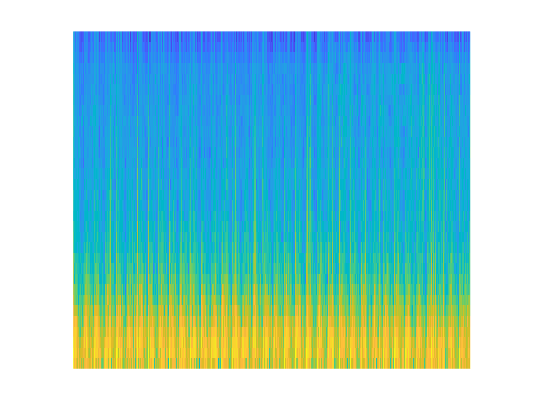


hold off

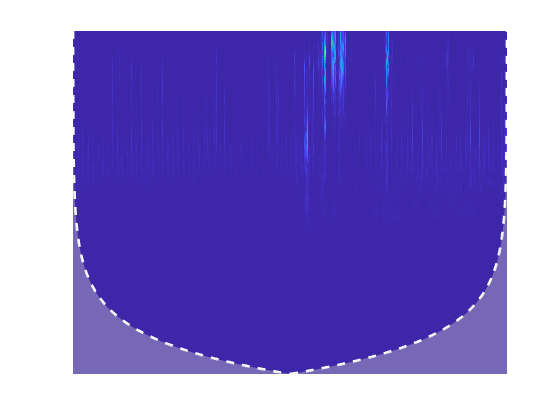

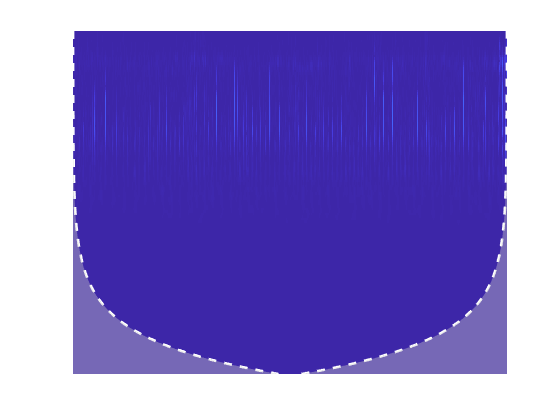

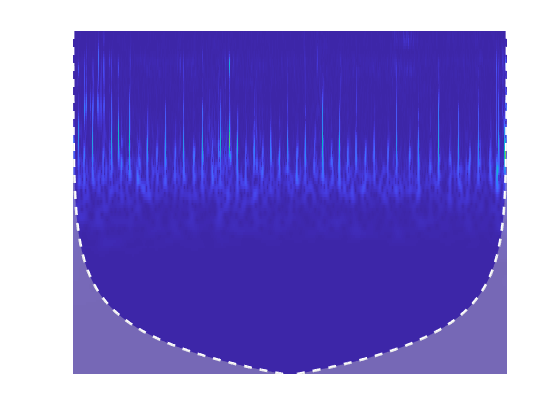

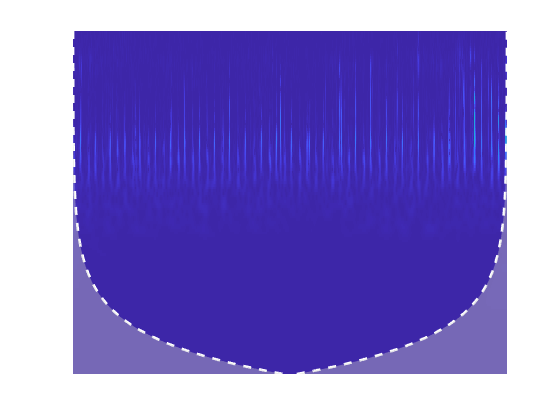

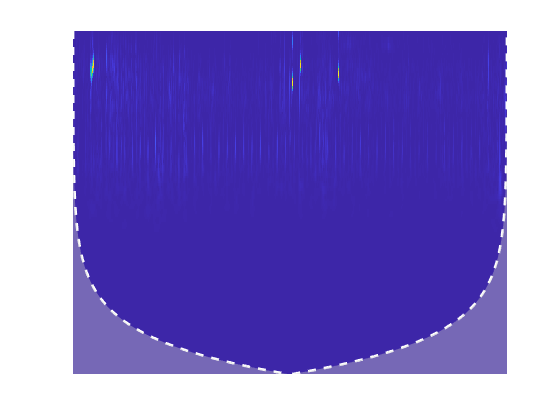

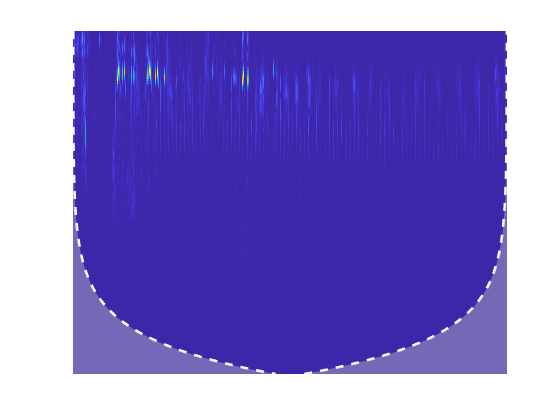

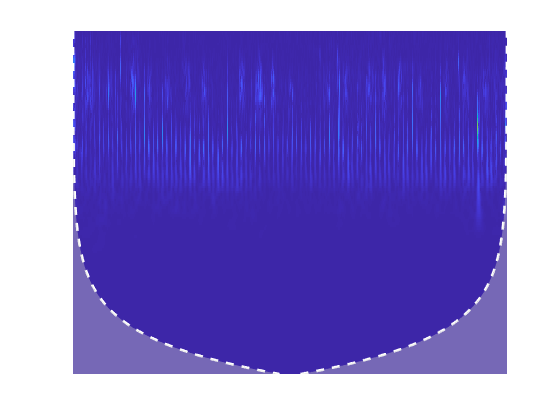

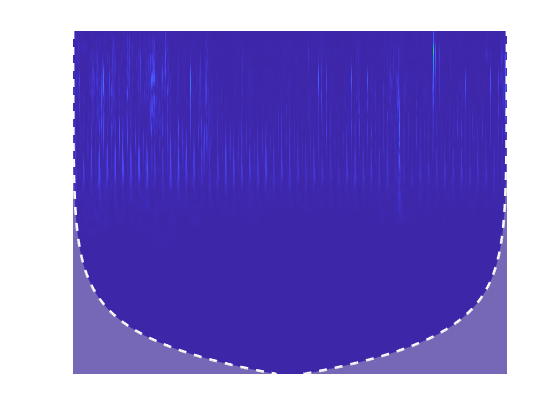

%ウェーブレット変換

for i = 1:length(listing)
    fullpath = fullfile(listing(i).folder, listing(i).name);
    [audioIn,fs] = audioread(fullpath);
    
    [wt,f] = cwt(audioIn);
    
    figure
    hold on
    cwt(audioIn,1);
    
    ax = gca;
    ax.YAxis.Visible = 'off';
    ax.XAxis.Visible = 'off';
    colorbar('off');
    title([]);
    
    %figureの画像を保存
    %saveas(gcf,'chart(i).png')
end

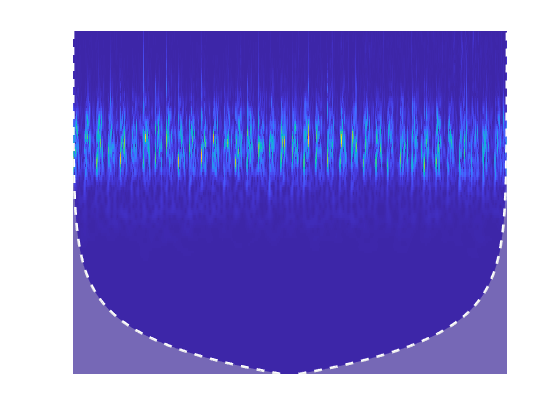


hold off

%resnet

%画像の読み込み
%{


%}
net = resnet50();

出力引数が多すぎます。

analyzeNetwork(net)

lgraph = layerGraph(net);

%全結合層を置き換えたい
%{
newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
%}












